## Actuator and Delay

d0 = 1;
n0 = 1;
tau1 = 0.03;
n1 = -tau1/2;
d1 = tau1/2;
s = tf('s');
tau2 = 10;
delay = (n0+n1*s)/(d0+d1*s)

delay =
 
  -0.015 s + 1
  ------------
  0.015 s + 1
 
Continuous-time transfer function.



actuator = 1/(tau2*s +1)

actuator =
 
     1
  --------
  10 s + 1
 
Continuous-time transfer function.




int = 1/s

int =
 
  1
  -
  s
 
Continuous-time transfer function.



## Throttle

TA = [0 1; -2.886  -1.464];
TB = [0; -0.04156];
TC = eye(2);
TD = 0;
x0 = [-1; -1];
Tsys = ss(TA,TB,TC,TD);
%[tb, ta] = ss2tf(TA, TB, TC, TD)


Q = diag([3; 1]);
R = 0.0002;
[Kt P R] = lqr(Tsys, Q, R);
Kt

Kt =   -71.3494  -63.1326


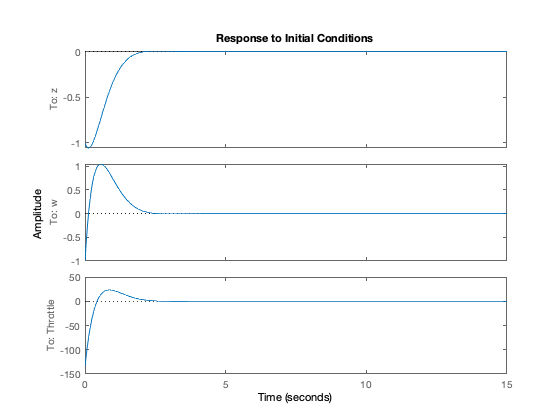

figure; 
Tcrit = ss(TA-TB*Kt, TB, [TC; -Kt], TD, 'OutputName', {'z', 'w', 'Throttle'}); 
initial(Tcrit, x0, 15)

## Elevator

EA = [0      1      0      0;
      -1027   -75.09   -672.2   -168.8;
      0      0      0      1;
      51.48  -0.4241     3.08   0.5621];
EB = -[0; -5.728; 0; -0.02711]; 
EC = diag([1 1 1 1]);
ED = 0;
x0 = [1 1 1 1];
Esys = ss(EA,EB,EC,ED);
Q = diag([1; 5; 6; 1]);
R=0.01;
[Ke P R] = lqr(Esys, Q, R);
Ke

Ke =   187.3795   13.8788   23.8627   18.2605


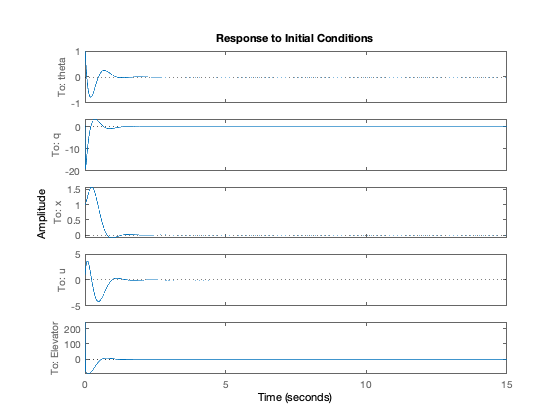

figure; 
Ecrit = ss(EA-EB*Ke, EB, [EC; Ke], ED, 'OutputName', {'theta', 'q', 'x', 'u', 'Elevator'});
initial(Ecrit,x0, 15)

## Aileron

AA = [0    1.0000         0         0;
     -1059  -154.6  -530.9  -297.1;
      0         0         0    1.0000;
      87.55   1.406   4.571   2.227];
AB = -[0; -8.511; 0; 0.0772];
AC = eye(4);
AD = 0;
Asys = ss(AA,AB,AC,AD);
[AK As AP] = lqr(Asys,eye(4),1);
x0 = [1 1 1 1];
Q = diag([1; 5; 6; 1]);
R = 0.009;
[Ka P R] = lqr(Asys, Q, R);
Ka

Ka =   204.3189   12.5647    4.4619    5.0928


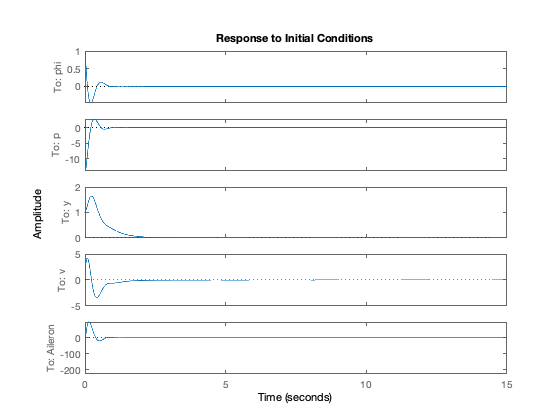

figure;
Acrit = ss(AA-AB*Ka, AB, [AC; -Ka], AD, 'OutputName', {'phi', 'p', 'y', 'v', 'Aileron'}); 
initial(Acrit,x0, 15)

## Rudder

RA = [0 1;  0.4381  -0.7692];
RB = [0; -0.1707];
RC = eye(2);
RD = 0;
Rsys = ss(RA,RB,RC,RD);
[RK, Rs RP] = lqr(Rsys,eye(2),1);
x0 = [1 1];
Q = diag([1.5; 1]);
R = 0.0001;
[Kr P R] = lqr(Rsys, Q, R);
Kr

Kr =  -125.0679 -102.6650


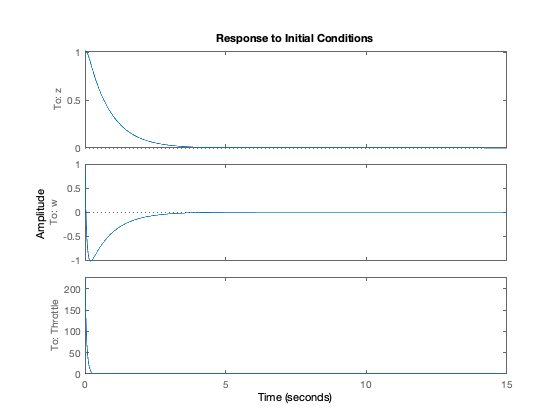

figure; 
Rcrit = ss(RA-RB*Kr, RB, [RC; -Kr], RD, 'OutputName', {'z', 'w', 'Throttle'}); 
initial(Rcrit,x0, 15)

## K Values

Kt

Kt =   -71.3494  -63.1326


Ke

Ke =   187.3795   13.8788   23.8627   18.2605


Ka

Ka =   204.3189   12.5647    4.4619    5.0928


Kr

Kr =  -102.5994  -84.3143


## Functions

function leg = createLegendVec(starttimes)
    for i = 1:length(starttimes)
       leg(i) = cellstr(append('Scale: ', string(starttimes(i))));
    end
end